img_file="Sample1.jpg"

img_file = "Sample1.jpg"

img=imread(img_file);%8 11 p5 20'

command=append("python YoloPytorch_Model/detect.py --weights YoloPytorch_Model/best.pt --img 416 --save-crop --exist-ok --source ",img_file)

command = "python YoloPytorch_Model/detect.py --weights YoloPytorch_Model/best.pt --img 416 --save-crop --exist-ok --source Sample1.jpg"

system(command)

□□detect: □weights=['YoloPytorch_Model/best.pt'], source=Sample1.jpg, data=YoloPytorch_Model\data\coco128.yaml, imgsz=[416, 416], conf_thres=0.25, iou_thres=0.45, max_det=1000, device=, view_img=False, save_txt=False, save_conf=False, save_crop=True, nosave=False, classes=None, agnostic_nms=False, augment=False, visualize=False, update=False, project=YoloPytorch_Model\runs\detect, name=exp, exist_ok=True, line_thickness=3, hide_labels=False, hide_conf=False, half=False, dnn=False, vid_stride=1 
YOLOv5  2022-12-24 Python-3.9.6 torch-2.1.0+cu121 CUDA:0 (NVIDIA GeForce GTX 1650, 4096MiB) 
 
Fusing layers...  
Model summary: 157 layers, 7012822 parameters, 0 gradients, 15.8 GFLOPs 
image 1/1 E:\8voCiclo\PSID\Proyecto2\CodeFinal\Sample1.jpg: 224x416 1 license_plate, 41.5ms 
Speed: 1.0ms pre-process, 41.5ms inference, 2.0ms NMS per image at shape (1, 3, 416, 416) 
Results saved to □YoloPytorch_Model\runs\detect\exp□ 
□□requirements:□ E:\8voCiclo\PSID\Proyecto2\CodeF

ans = 0


img=imread(append("YoloPytorch_Model\runs\detect\exp\crops\license_plate\",img_file))

img = 122×296×3 uint8 array
img(:,:,1) =

   116   106   111    79    51    16     6    10    21    22    22    18    17    18    17    16    15    15    14    13    15    16    17    19    22    22    21    19    18    17    17    18    21    23    22    22    19    15    13    15    16    18    18    23    26    23    16    15    15    17    22    24    24    24    22    22    25    19    20    28    30    24    23    28    24    25    26    29    31    34    37    38    38    42    45    41    38    38    40    42    45    46    46    42    41    42    42    41    39    41    43    44    44    45    45    43    46    49    47    46    49    46    46    49    46    50    52    49    49    51    49    47    45    47    43    41    42    42    41    42    45    48    46    38    36    43    47    42    30    30    31    38    47    45    44    46    43    42    38    34    34    36    34    31    31    36    32    29    29    28    31    34    32    32    33    36    40    39    38    

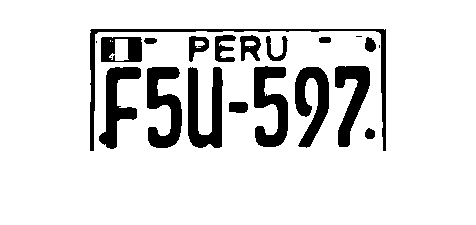

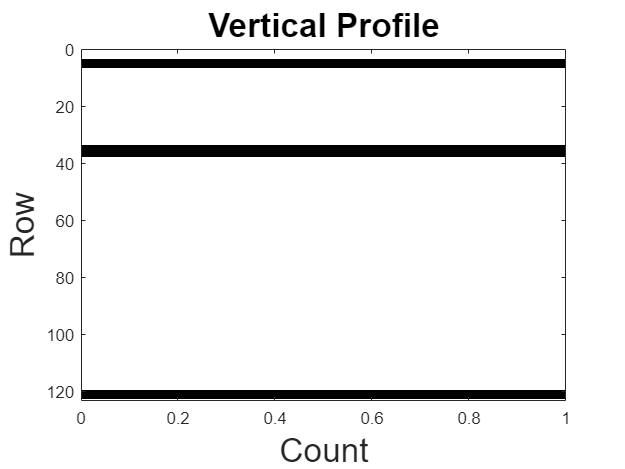

inicio = 2

inicio = 7

fin = 34

inicio =      7    38


fin =     34   120


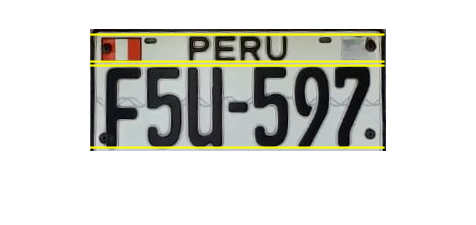

[ini, fin]= deteccionLineas(img,95,10);

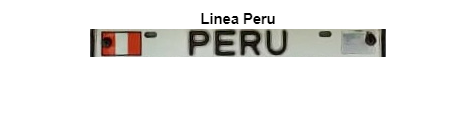


lineaPeru=img(ini(1):fin(1),1:size(img,2),:);
lineaNumeroPlaca=img(ini(2):fin(2),1:size(img,2),:);
imshow(lineaPeru);title("Linea Peru");

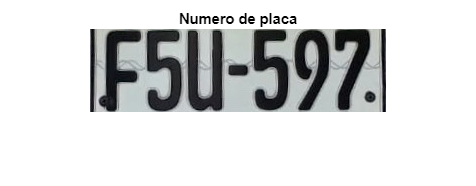

imshow(lineaNumeroPlaca);title("Numero de placa")

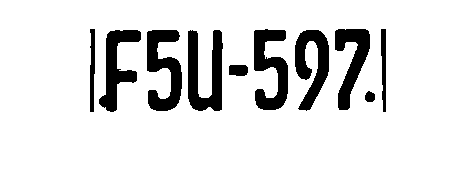

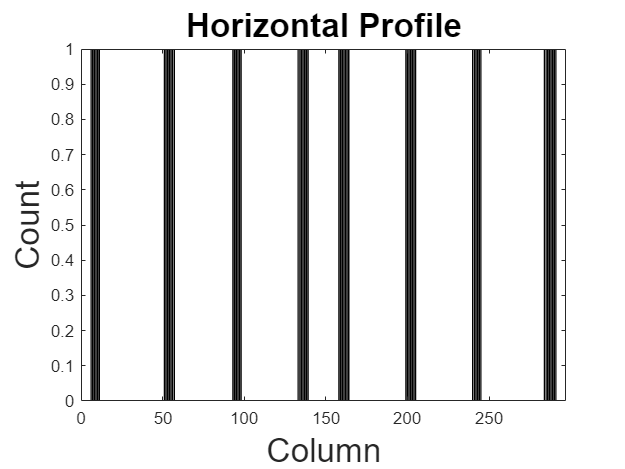

umbralAnchoPalabra=2;
[ini, fin]=SegmentacionCaracteres(lineaNumeroPlaca,90,umbralAnchoPalabra);

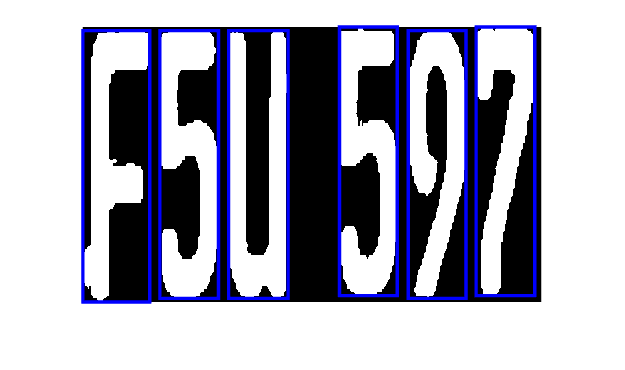

    "El caracter es: F"



caracter = 'F'

    "El caracter es: 5"



caracter = '5'

    "El caracter es: U"



caracter = 'U'

    "El caracter es: 5"



caracter = '5'

    "El caracter es: 9"



caracter = '9'

    "El caracter es: 7"



caracter = '7'

lineaNumeroPlaca=lineaNumeroPlaca(1:size(lineaNumeroPlaca,1),ini(1):fin(end),:);

%Detección del número de placa
[numeroPlaca]=Segmentacion(lineaNumeroPlaca);

display("La placa es: " + numeroPlaca);

    "La placa es: F5U597"



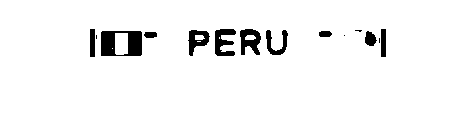

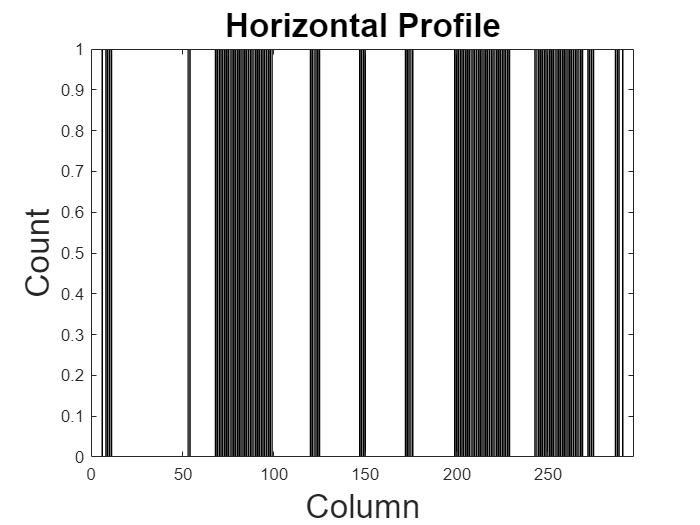


%Verificación del país de origen de la placa
[ini, fin]=SegmentacionCaracteres(lineaPeru,97,umbralAnchoPalabra);

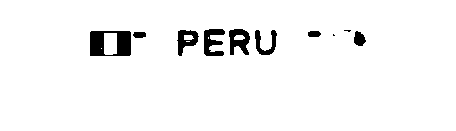

etiquetado =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [1 1 1]
    Position: [488 242 544 322.4000]
       Units: 'pixels'

  Show all properties


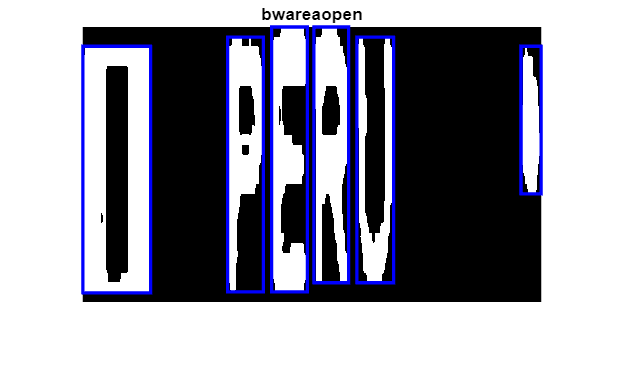

lineaPeru=lineaPeru(1:size(lineaPeru,1),ini(1):fin(end),:);
[pais]=SegmentacionPeru(lineaPeru);

k=strfind(pais,"PERU");
if size(k)==0
    display("La placa no es peruana" );
else
    display("La placa es peruana" );
end

    "La placa es peruana"

